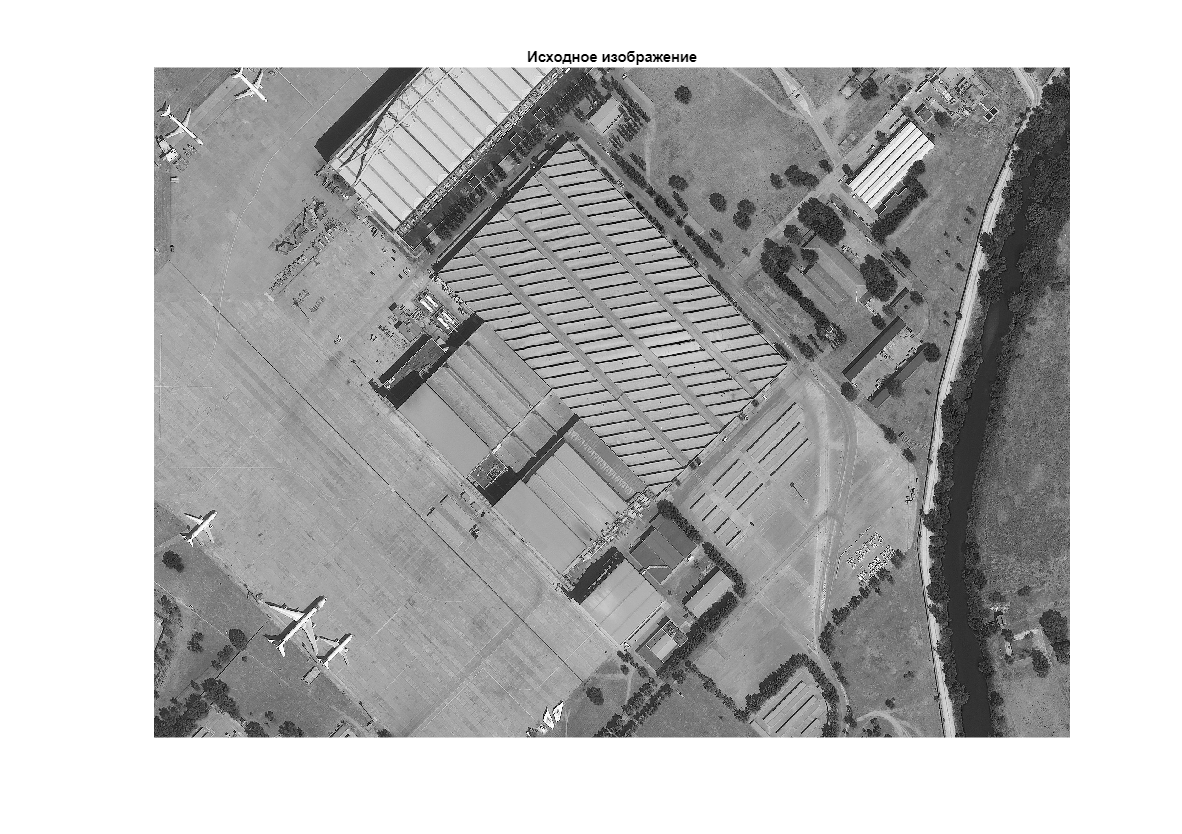

clc
clear
load("Test_im.mat")
Test = double(rgb2gray(Test_im))/255*0.9;
I = im2double(rgb2gray(imread('WorldView-3 Satellite Image Airport Mapping.jpg')))/2;
I=I(273:1735,:);
figure(1);imshow(I*2);title('Исходное изображение');

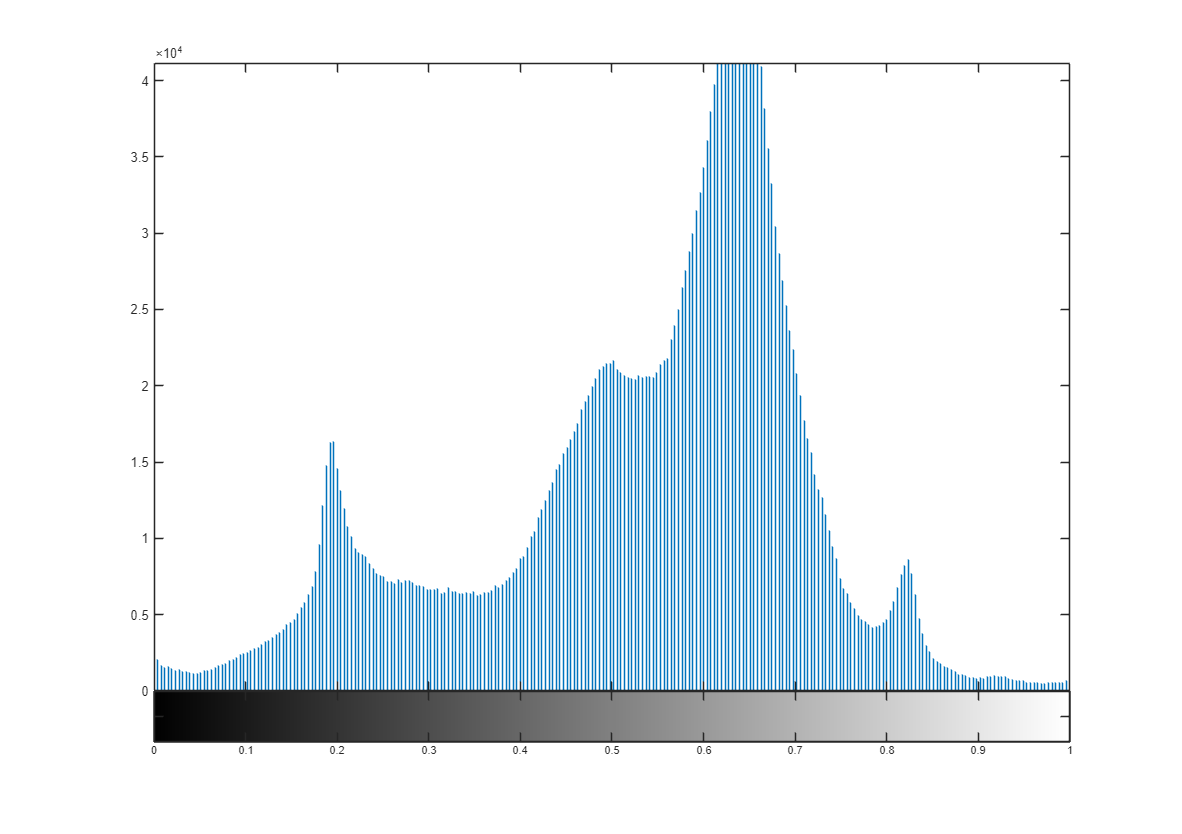

imhist(I*2)

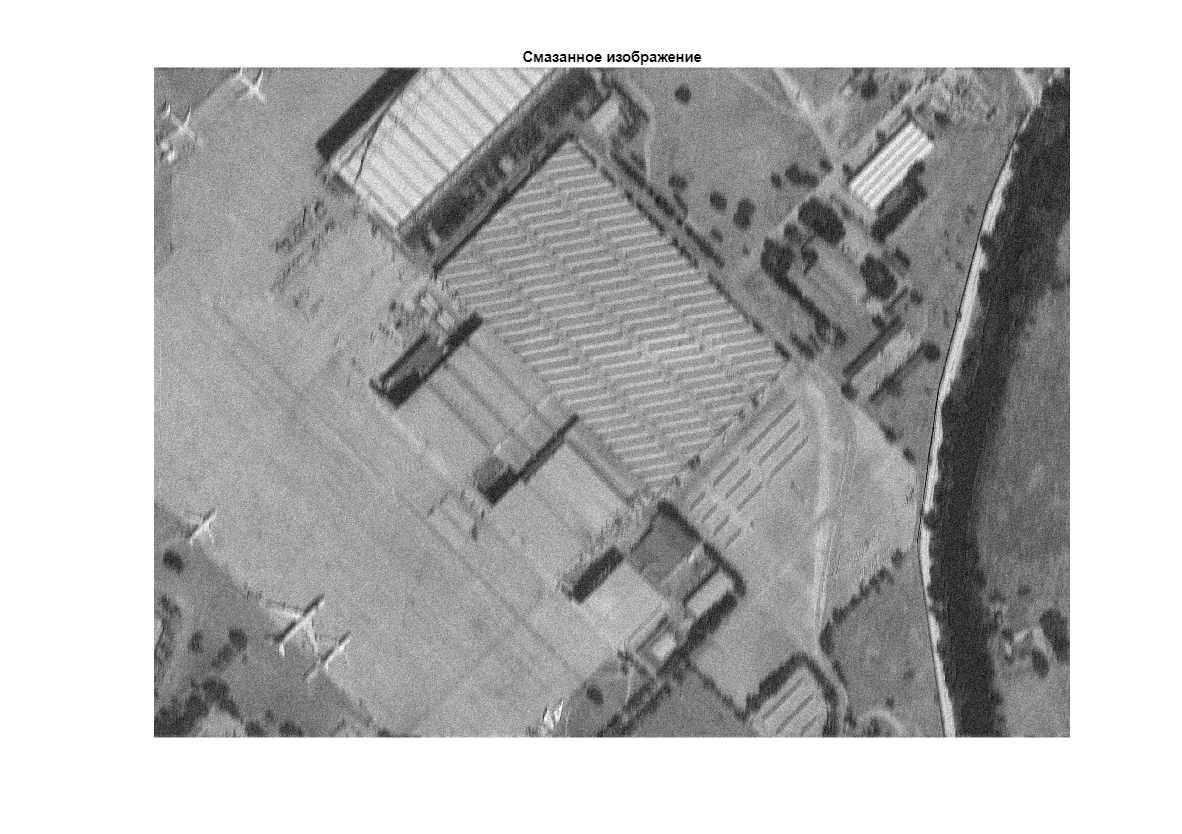

PSF2 =fspecial('disk', 7);
PSF =fspecial('motion', 17,85);
% Blur image
Blurred = imfilter(I, PSF,'circular','conv' );

% Add noise
noise_mean = 0.002;
noise_var = 0.0005;
Blurred_smaz = imnoise(Blurred, 'gaussian', noise_mean, noise_var);
figure(2); imshow(Blurred_smaz*2); title('Смазанное изображение')

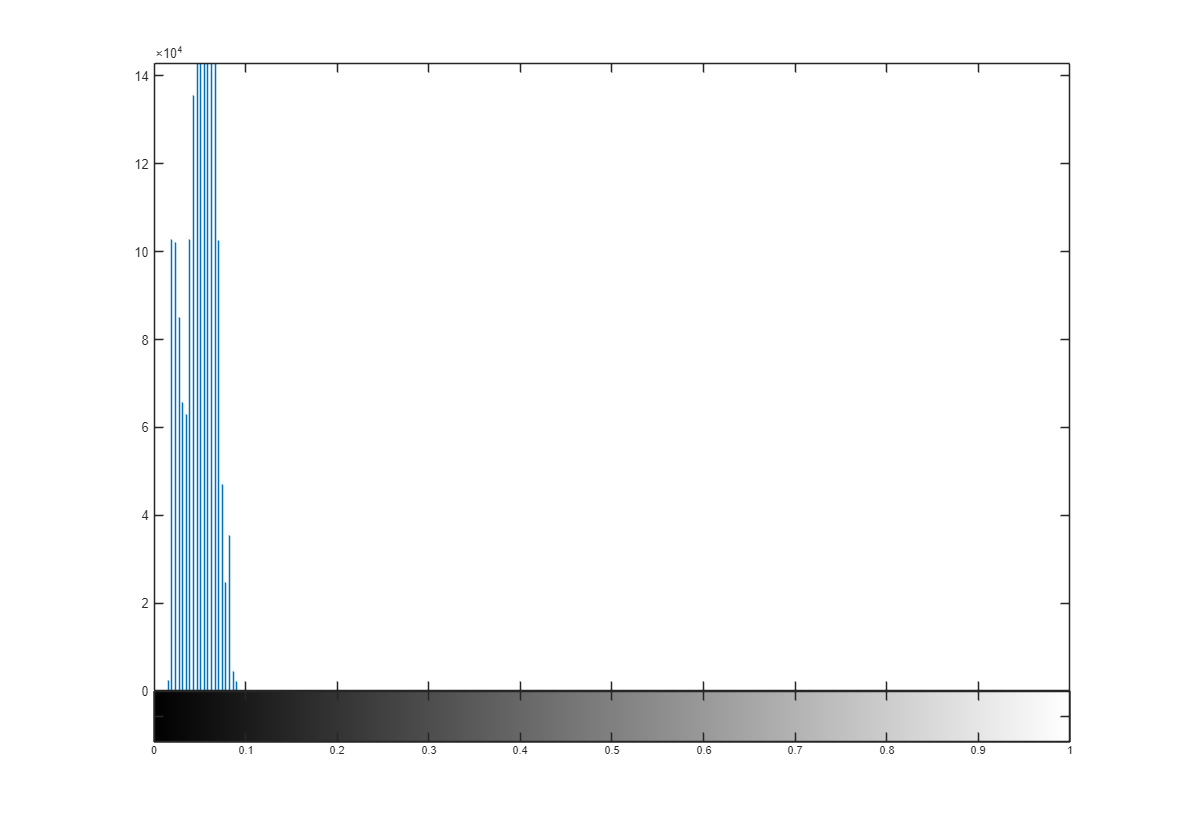

% Субэкспозиция
Blurred_sub1=zeros(1463,2000);
Blurred = imfilter(I, PSF2,'circular','conv' )/5;
imhist(Blurred)

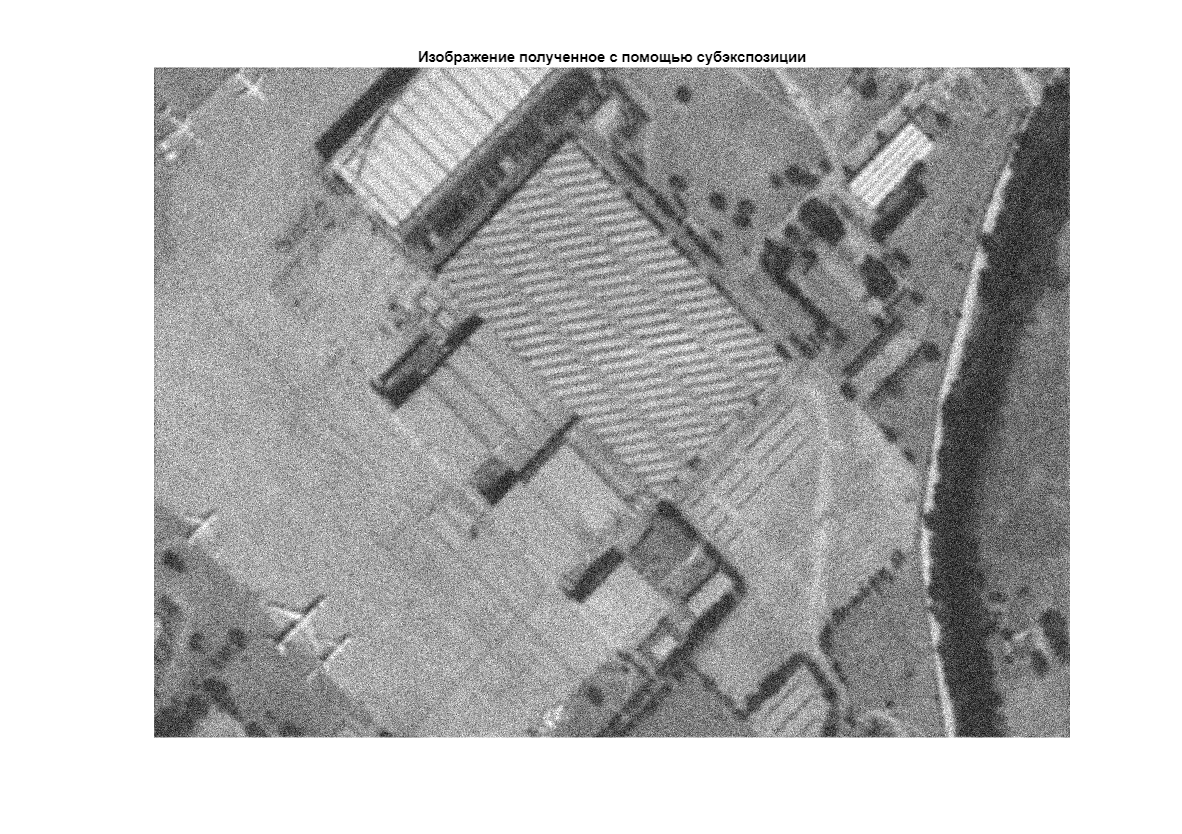

step=5;
for i =1:step
Blurred_sub = imnoise(Blurred, 'gaussian', noise_mean, noise_var);
Blurred_sub1 =Blurred_sub1 +Blurred_sub;
end
figure(2); imshow(Blurred_sub1*2); title('Изображение полученное с помощью субэкспозиции');

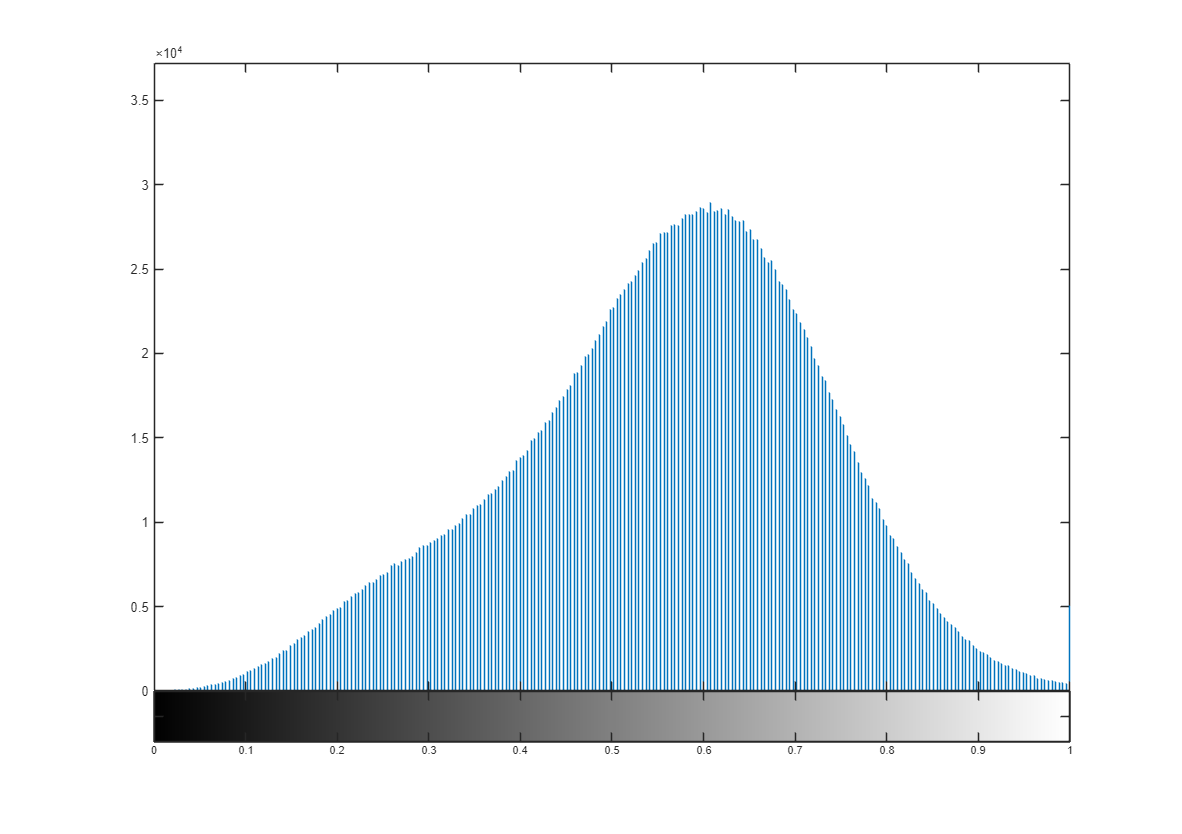

imhist(Blurred_sub1*2)

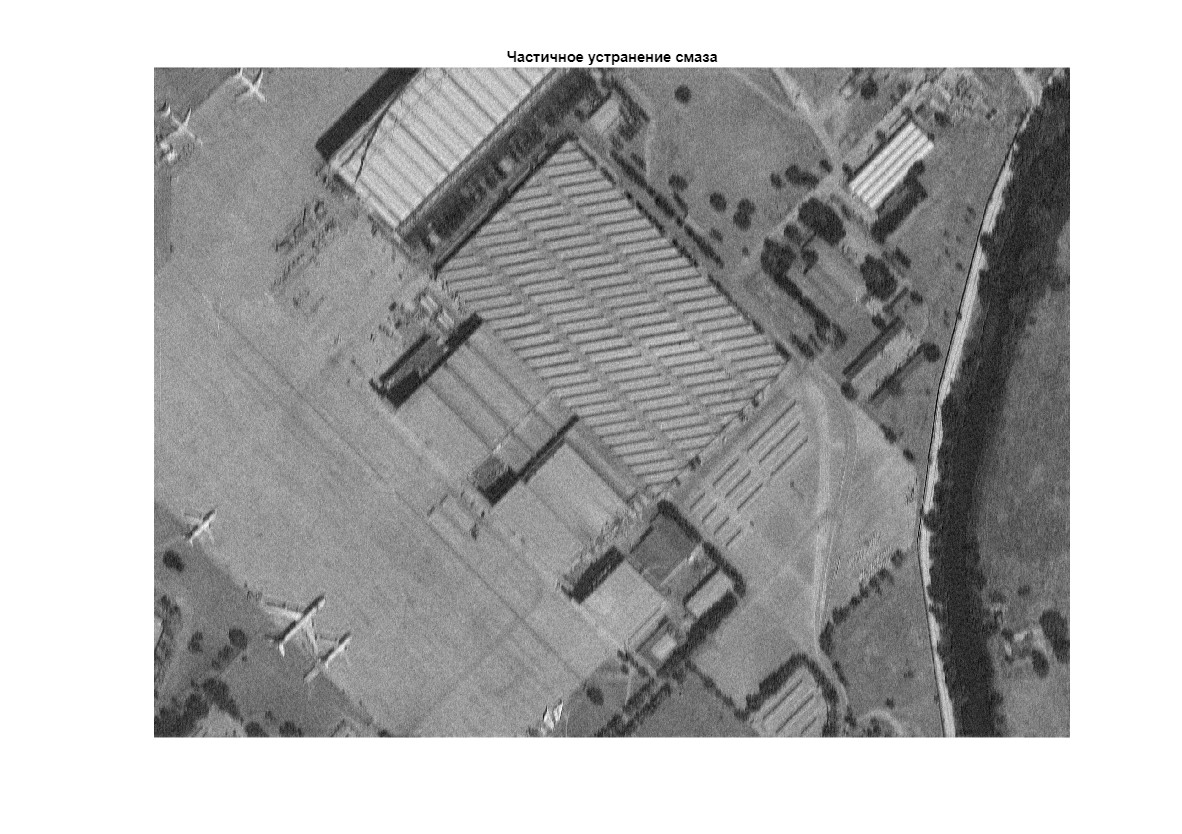

% Deconvolution
% figure(3); imshow(deconvwnr(Blurred, PSF, 0)); title('Результат');
estimated_nsr = noise_var / var(Blurred_smaz(:));
% Restore image
figure(4), imshow(deconvwnr(Blurred_smaz, PSF, estimated_nsr)*2), title('Частичное устранение смаза');

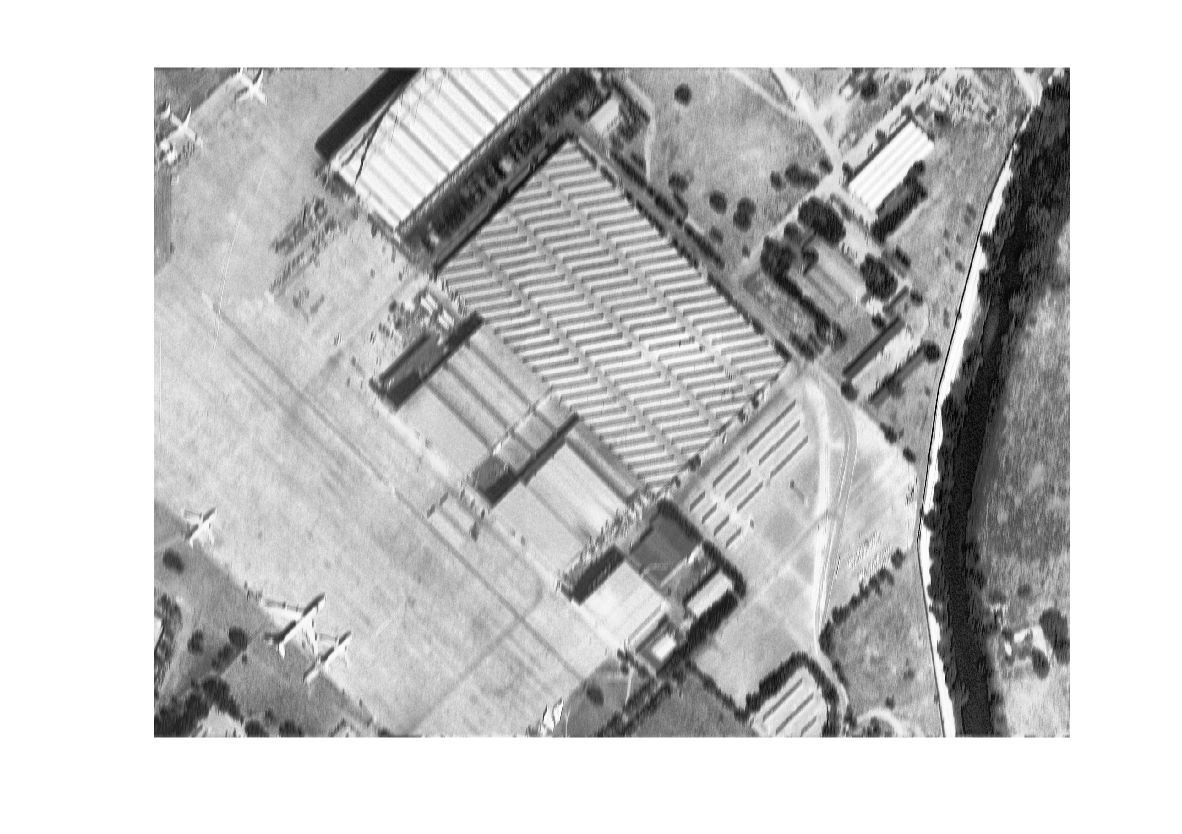

img ={uint16(Blurred*255*255),uint16(deconvwnr(Blurred_smaz, PSF, estimated_nsr)*255*255)};
hdr = makehdr(img,'RelativeExposure',[1,3]);
hdr2 = tonemap(hdr);
imshow(hdr2), title('Совмещённый HDR');

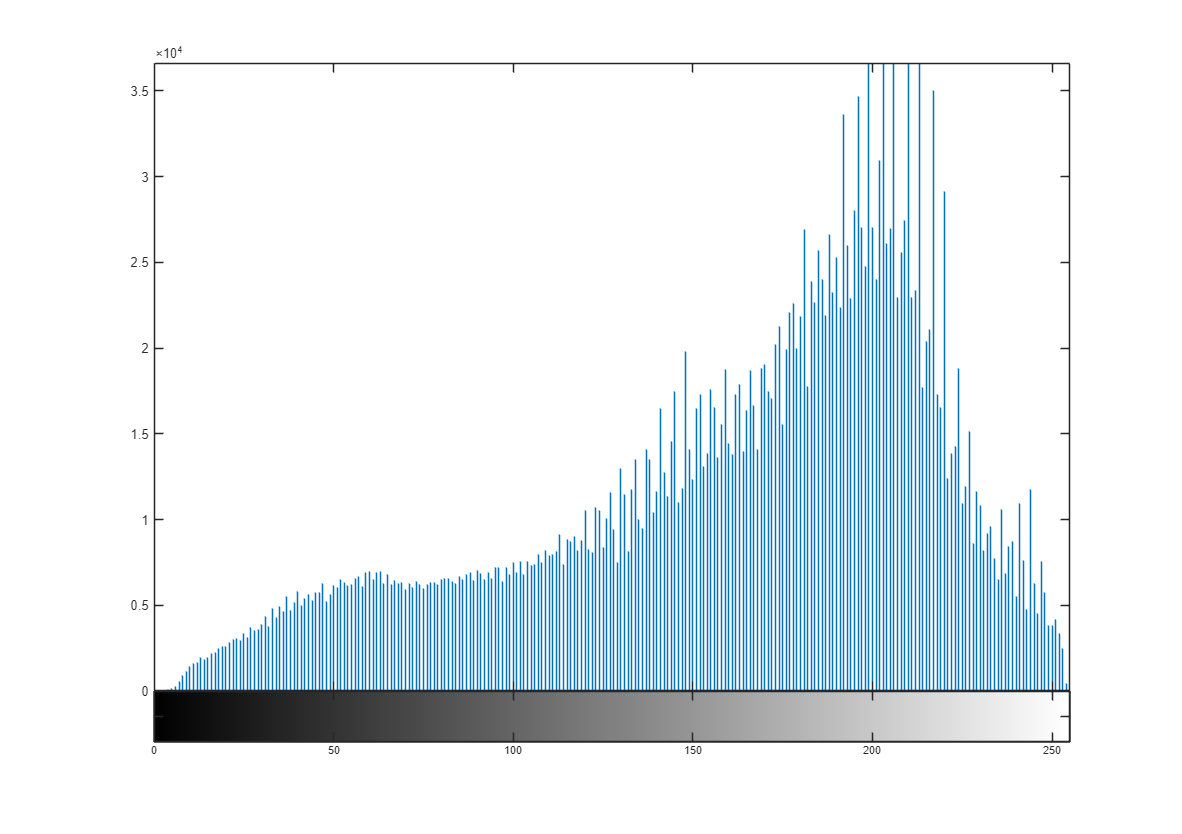

imhist(hdr2)